%PART 1.a
%block 1
                            %STATUS: COMPLETE
%Goal: Create signal with voice 

%f_s=44000;                                  %Sampling freq that follows Nyquist Theorem

%voice_rec = audiorecorder(f_s,8,1);                  %Creates object named voice_recorder
%pause(2);                                   %Pauses for 2 sec to give time 
%disp('Start Speaking');
%recordblocking(voice_rec, 2);               %records voice for 4 sec
%disp('Stop speaking');


%play(voice_rec);                           %Playback

%voice_data = getaudiodata(voice_rec);      %Stores the voice_rec to data in voice_data

%save ('Comm_Audio_Rec.mat', 'voice_data','f_s');   %saves my info to a file 


% Provide the code to playback the audio from your .mat file.
%load('Comm_Audio_Rec.mat','voice_data','f_s'); %loads variables from the file name 



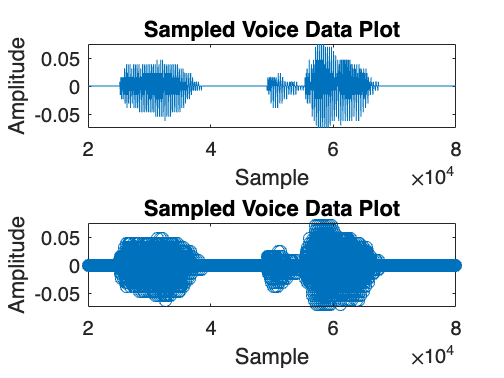

% PLOTING VOICE DATA
%block 2
                        %STATUS: COMPLETE

load('Comm_Audio_Rec.mat','voice_data','f_s'); %loads variables from the file name 
%sound(voice_data,f_s);   

voice_data= voice_data';                % Did a transpoe to get the array horizontally 
voice_sample_axis = 0:88000-1;       %sets the x axis of the voice data
figure();
subplot(2, 1, 1);
plot(voice_sample_axis, voice_data);
xlim([20000 80000]);
ylim([-0.075 0.075]);
xlabel("Sample");
ylabel("Amplitude");
title("Sampled Voice Data Plot");

subplot(2, 1, 2);
stem(voice_sample_axis, voice_data);
xlim([20000 80000]);
ylim([-0.075 0.075]);
xlabel("Sample");
ylabel("Amplitude");
title("Sampled Voice Data Plot");

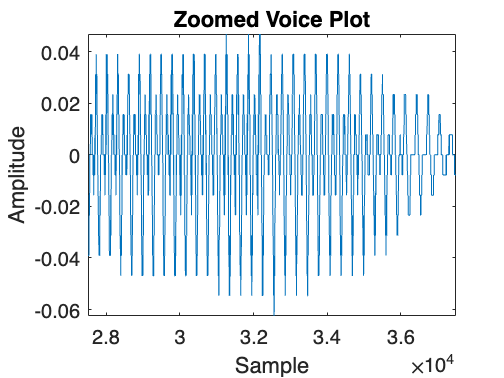


%Zoomed portion 
start= 27501; 
stop = 37500;

voice_data_zoom = voice_data(start:stop);
voice_zoom_axis = start:stop;
figure();
plot(voice_zoom_axis, voice_data_zoom);
xlabel("Sample");
ylabel("Amplitude");
title("Zoomed Voice Plot");
xlim([start stop]);

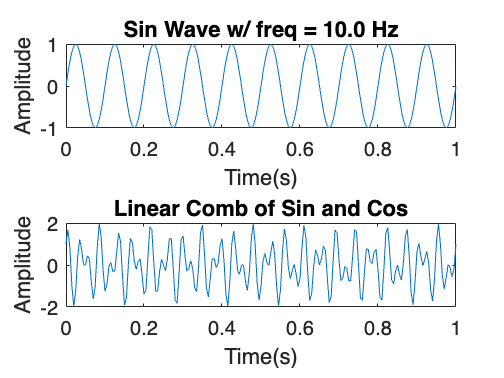

%Goal: Create a signal sinusoids
%block 3
                        %STATUS: COMPLETE
%sin
%t= 0:0.001:1;
t= 0:0.005:1;
sin_freq =10;           %frequency of sin wave 
s_t= sin(2*pi*sin_freq*t);
fs_sin = 1 / (t(2) - t(1)); % Compute sampling frequency from time st
figure();
subplot(2, 1, 1);
plot(t,s_t);
xlim([0, 1]);
title(sprintf("Sin Wave w/ freq = %.1f Hz", sin_freq));
xlabel('Time(s)');
ylabel( "Amplitude");

%cos
cos_freq =23;
c_t= cos(2*pi*cos_freq*t)+sin(2*pi*(cos_freq+15)*t);    %Linear Comb 

subplot(2, 1, 2);
plot(t,c_t);
xlim([0, 1]);
title("Linear Comb of Sin and Cos");
xlabel('Time(s)');
ylabel("Amplitude");


%This section of the code is to create two sinusiouds that will also be
%used for system. One is a sine and the other is a linear combination of
%the sine and cosine. 

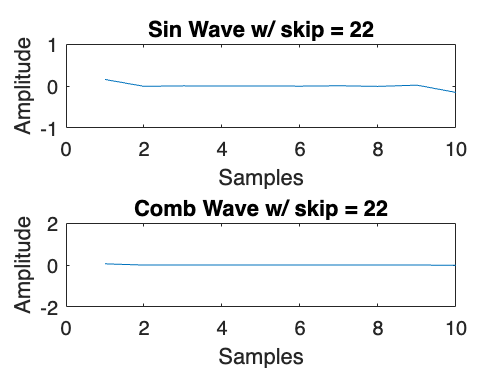

% Resample signal s_t and c_t
%block 4

%Status: COMPLETE

%Resample function in matlab 

skip_Val=22;    %Assigning the skip // Esentially Ts

s_t_resampled= resample(s_t,1,skip_Val);     %Only reading the skip value 

c_t_resampled= resample(c_t,1,skip_Val);     %Only reading the skip value 

figure();
subplot(2, 1, 1);
plot(s_t_resampled);
ylim([-1 1]);

ylabel("Amplitude");
xlabel("Samples");
title(sprintf("Sin Wave w/ skip = %.f", skip_Val));



subplot(2, 1, 2);
plot(c_t_resampled);
ylim([-2 2]);
ylabel("Amplitude");
xlabel("Samples");
title(sprintf("Comb Wave w/ skip = %.f", skip_Val));

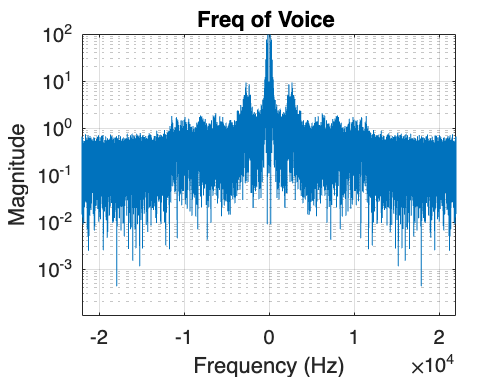

%GOAL: DFT Analysis
%block 5
                    %STATUS: COMPLETE
      

%DFT of voice signal 
X_K_Voice = fft(voice_data); %does the DFT of signal
N_0 = length(voice_data);    %Creates vector same size as voice_data 
f_k = (0:length(X_K_Voice)-1)/N_0*f_s;  %Creates frequency axis 
figure;
f_k_shift = f_k - f_s/2; % shift the axis so that it is centered at 0
plot(f_k_shift,fftshift(abs(X_K_Voice))); %plots the new graph
xlabel('Frequency (Hz)');
ylabel('Magnitude');
set(gca, 'YScale', 'log'); 
yticks(10.^(-3:1:3));
title("Freq of Voice ");
grid on;

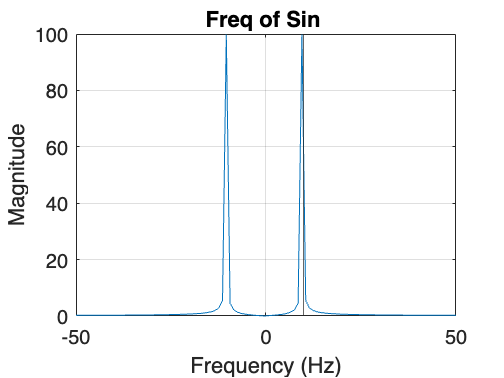


%DFT of signal s_t  
X_K_Sin = fft(s_t); %does the DFT of signal
N_0 = length(s_t);    %Creates vector same size as voice_data 
f_k = (0:length(s_t)-1)/N_0*fs_sin;  %Creates frequency axis 
figure;
f_k_shift = f_k - fs_sin/2; % shift the axis so that it is centered at 0
plot(f_k_shift,fftshift(abs(X_K_Sin))); %plots the new graph
xlabel('Frequency (Hz)');
ylabel('Magnitude');
%set(gca, 'YScale', 'log'); 
%yticks(10.^(-3:1:3));
xlim( [ -50 50]);
title("Freq of Sin ");
grid on;
xline(10);

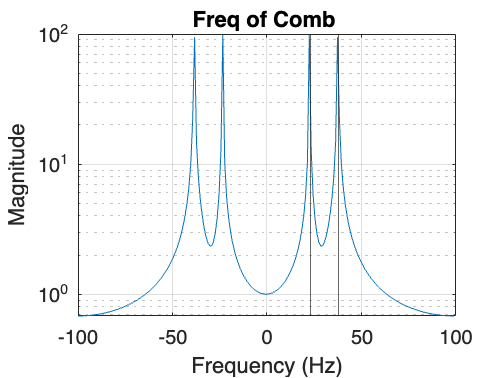


%Normalization: Normalize amplitude for 0dB 



%DFT of signal c_t  
X_K_Comb = fft(c_t); %does the DFT of signal
N_0 = length(c_t);    %Creates vector same size as voice_data 
f_k = (0:length(c_t)-1)/N_0*fs_sin;  %Creates frequency axis 
figure;
f_k_shift = f_k - fs_sin/2; % shift the axis so that it is centered at 0
plot(f_k_shift,fftshift(abs(X_K_Comb))); %plots the new graph
xlabel('Frequency (Hz)');
ylabel('Magnitude');
set(gca, 'YScale', 'log'); 
yticks(10.^(-3:1:3));
xlim( [ -100 100]);
title("Freq of Comb ");
grid on;
xline(38);
xline(23);

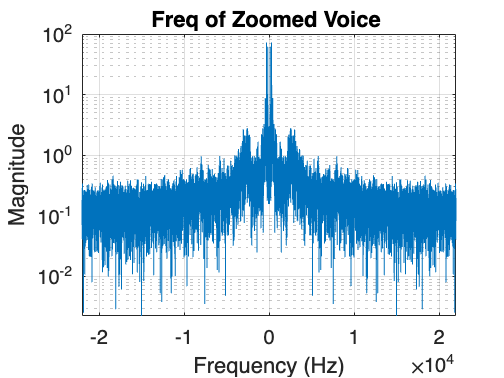


%DFT of Zoom voice 
X_K_Voice_Zoom = fft(voice_data_zoom); %does the DFT of signal
N_0 = length(voice_data_zoom);    %Creates vector same size as voice_data 
f_k = (0:length(voice_data_zoom)-1)/N_0*f_s;  %Creates frequency axis 
figure;
f_k_shift = f_k - f_s/2; % shift the axis so that it is centered at 0
plot(f_k_shift,fftshift(abs(X_K_Voice_Zoom))); %plots the new graph
xlabel('Frequency (Hz)');
ylabel('Magnitude');
set(gca, 'YScale', 'log'); 
yticks(10.^(-3:1:3));
title("Freq of Zoomed Voice ");
grid on;

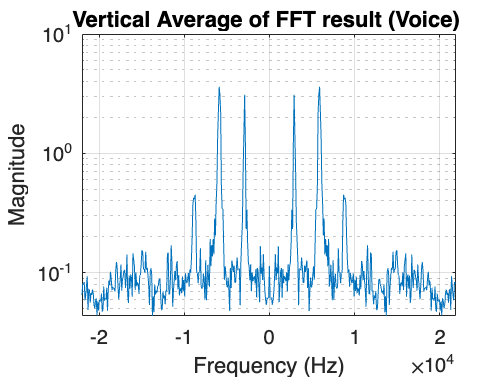

%Reshape zoomed part of voice 
%block 6
                        %Status: COMPLETE
%
reshape_voice = reshape(voice_data_zoom, [20 500]); %splits the voice signal into 20 rows and 500 columns->10000

X_K_Matrix = fft(reshape_voice.').';    %Computes the fft of each row

X_K_Matrix = mean(abs(X_K_Matrix), 1);  %Computes the vertical mean for each row


%Shifting
N_0 = length(reshape_voice);    %Creates vector same size as voice_data 
f_k = (0:length(reshape_voice)-1)/N_0*f_s;  %Creates frequency axis 
figure;
f_k_shift = f_k - f_s/2; % shift the axis so that it is centered at 0
plot(f_k_shift,fftshift(abs(X_K_Matrix))); %plots the new graph
xlabel('Frequency (Hz)');
ylabel('Magnitude');
set(gca, 'YScale', 'log');  %Logarithmic 
yticks(10.^(-2:1:1));   %step of y axis from -10^-2 to 10^1 by 10
title("Vertical Average of FFT result (Voice) ");
grid on;

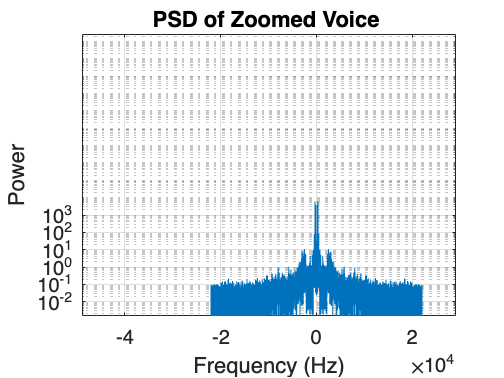

                        % POWER SPECTRAL DENSITY 
                        %Statue: Complete 
                        %block 7

%zoomed Voice                        
%autocorrelation 
auto_corr_zoomed_voice = xcorr(voice_data_zoom);
%DFT of Zoom voice 
power_zoomed_voice = fft(auto_corr_zoomed_voice); %does the DFT of signal
N_0 = length(auto_corr_zoomed_voice);    %Creates vector same size as voice_data 
f_k = (0:length(auto_corr_zoomed_voice)-1)/N_0*f_s;  %Creates frequency axis 
figure;
f_k_shift = f_k - f_s/2; % shift the axis so that it is centered at 0
plot(f_k_shift,fftshift(abs(power_zoomed_voice))); %plots the new graph
xlabel('Frequency (Hz)');
ylabel('Power');
set(gca, 'YScale', 'log'); 
yticks(10.^(-3:1:3));
title("PSD of Zoomed Voice ");
grid on;

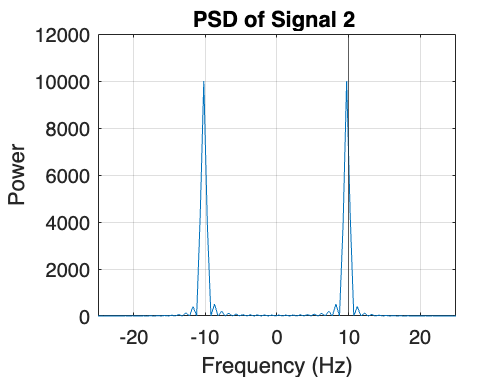



%PSD of signal 2 
%autocorrelation 
auto_corr_s2 = xcorr(s_t);
%DFT of Zoom voice 
power_s2 = fft(auto_corr_s2); %does the DFT of signal
N_0 = length(auto_corr_s2);    %Creates vector same size as voice_data 
f_k = (0:length(auto_corr_s2)-1)/N_0*fs_sin;  %Creates frequency axis 
figure;
f_k_shift = f_k - fs_sin/2; % shift the axis so that it is centered at 0
plot(f_k_shift,fftshift(abs(power_s2))); %plots the new graph
xlabel('Frequency (Hz)');
ylabel('Power');
%set(gca, 'YScale', 'log'); 
%yticks(10.^(-3:1:4));
title("PSD of Signal 2 ");
grid on;
xline(10);
xlim([ -25 25]);

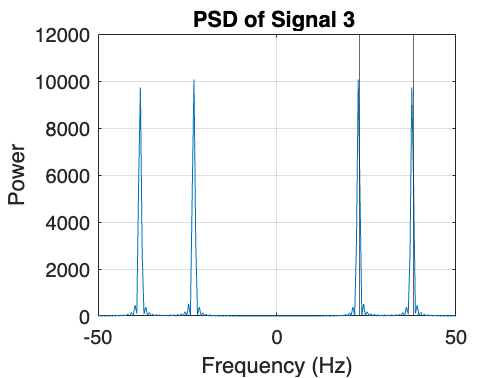


%PSD of signal 3 
%autocorrelation
auto_corr_s3 = xcorr(c_t);
%DFT of Zoom voice 
power_s3 = fft(auto_corr_s3); %does the DFT of signal
N_0 = length(auto_corr_s3);    %Creates vector same size as voice_data 
f_k = (0:length(auto_corr_s3)-1)/N_0*fs_sin;  %Creates frequency axis 
figure;
f_k_shift = f_k - fs_sin/2; % shift the axis so that it is centered at 0
plot(f_k_shift,fftshift(abs(power_s3))); %plots the new graph
xlabel('Frequency (Hz)');
ylabel('Power');
%set(gca, 'YScale', 'log'); 
%yticks(10.^(-3:1:5));
title("PSD of Signal 3 ");
grid on;
xlim([ -50 50]);
xline(38);
xline(23);


%This portion of the code is to view the power that each singal has againts
%freqeuncy. This is done by taking the autocorrelation of the signal in
%time domain and then computing the fourier transform of that data and
%plotting it. 

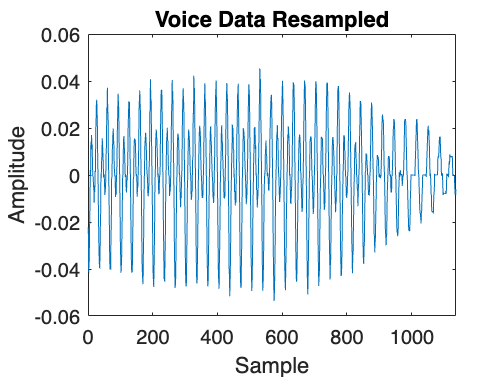

%Aliasing 
%block 8
                    %Status: Complete
%Resample voice 
f_s_aliasing_v=5000;
voice_data_zoom_resampled = resample(voice_data_zoom,f_s_aliasing_v,f_s);
%voice_data_zoom_resampled = resample(voice_data_zoom,f_s_aliasing_v,f_s);
plot(voice_data_zoom_resampled);
xlabel("Sample");
ylabel("Amplitude");
title("Voice Data Resampled");

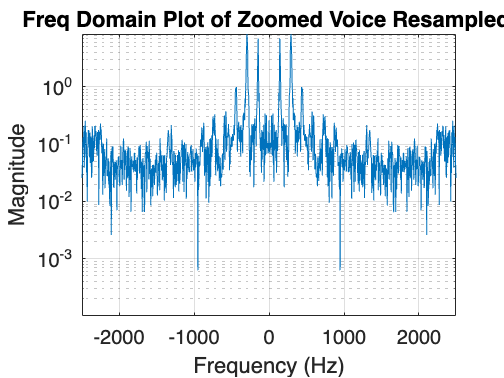


%DFT of Zoom voice 
X_K_Voice_Zoom_aliasing = fft(voice_data_zoom_resampled); %does the DFT of signal
N_0 = length(voice_data_zoom_resampled);    %Creates vector same size as voice_data 
f_k = (0:length(voice_data_zoom_resampled)-1)/N_0*f_s_aliasing_v;  %Creates frequency axis 
figure;
f_k_shift = f_k - f_s_aliasing_v/2; % shift the axis so that it is centered at 0
plot(f_k_shift,fftshift(abs(X_K_Voice_Zoom_aliasing))); %plots the new graph
xlabel('Frequency (Hz)');
ylabel('Magnitude');
set(gca, 'YScale', 'log'); 
yticks(10.^(-3:1:3));
title("Freq Domain Plot of Zoomed Voice Resampled ");
grid on;

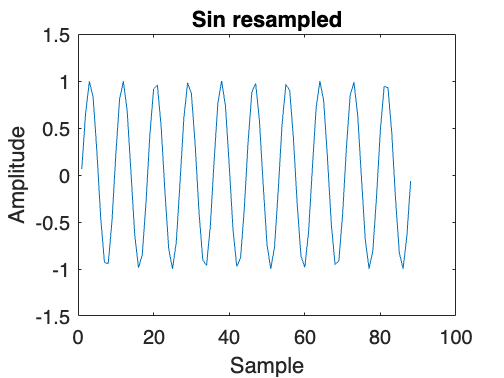


%Resampling of sine wave 
new_fs_s = 87;
s_t_resampled = resample(s_t, new_fs_s, fs_sin);
plot(s_t_resampled);
xlabel("Sample");
ylabel("Amplitude");
title("Sin resampled");
xlim([0 100]);

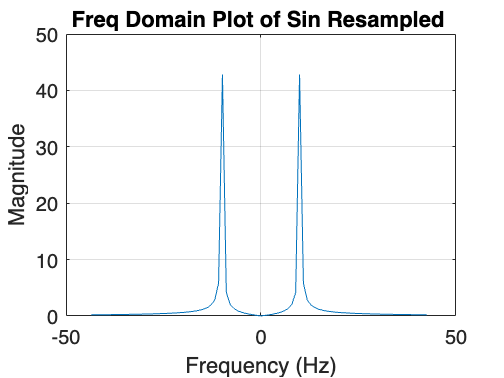

%DFT of resapmled sin 
X_K_sin_aliasing = fft(s_t_resampled); %does the DFT of signal
N_0 = length(s_t_resampled);    %Creates vector same size as voice_data 
f_k = (0:length(s_t_resampled)-1)/N_0*new_fs_s;  %Creates frequency axis 
figure;
f_k_shift = f_k - new_fs_s/2; % shift the axis so that it is centered at 0
plot(f_k_shift,fftshift(abs(X_K_sin_aliasing))); %plots the new graph
xlabel('Frequency (Hz)');
ylabel('Magnitude');
%set(gca, 'YScale', 'log'); 
%yticks(10.^(-3:1:3));
title("Freq Domain Plot of Sin Resampled ");
grid on;

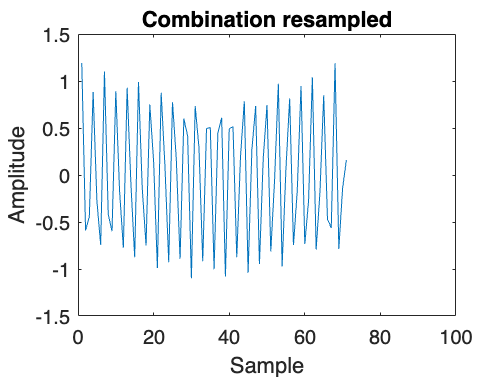


%Resampling of combination wave 
new_fs_c = 70;
c_t_resampled = resample(c_t, new_fs_c, fs_sin);
plot(c_t_resampled);
xlabel("Sample");
ylabel("Amplitude");
title("Combination resampled");
xlim([0 100]);

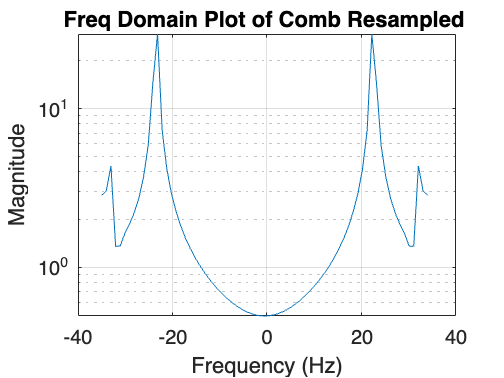

%DFT of resapmled sin 
X_K_comb_aliasing = fft(c_t_resampled); %does the DFT of signal
N_0 = length(c_t_resampled);    %Creates vector same size as voice_data 
f_k = (0:length(c_t_resampled)-1)/N_0*new_fs_c;  %Creates frequency axis 
figure;
f_k_shift = f_k - new_fs_c/2; % shift the axis so that it is centered at 0
plot(f_k_shift,fftshift(abs(X_K_comb_aliasing))); %plots the new graph
xlabel('Frequency (Hz)');
ylabel('Magnitude');
set(gca, 'YScale', 'log'); 
yticks(10.^(-3:1:3));
title("Freq Domain Plot of Comb Resampled ");
grid on;

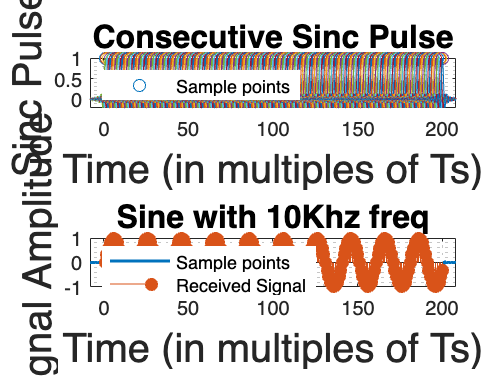

                           %STATUS: FALSE READINGS
%block 9
%Reconstruction of Sin
%addpath('/Users/ericdutan/Desktop/Spring 2025/Communications/MLX_Support_Files'); % add the location of your mlx filesclf;
%rng default

%testing
    %WE ARE USING THE RIGHT s_t
    %t= 0:0.005:1;
    %figure();
    %plot(t,s_t);
%end of testing 

n_symb = length(s_t)-1; % To not resample the signal, This is to ge the whole og signal
t = 1:n_symb;               %Create t axis w step size of 1 
%x = 1;%randi(size(t))'

    %ATTEMPTS
    %t_sin = (0:n_symb-1)/fs_sin;
    %sin_freq =10;           %frequency of sin wave 
    %s_t= sin(2*pi*sin_freq*t_sin);

    d2 = s_t(1:n_symb)';   %This works as we just take points from the sin
    %d2 = interp1(t_sinusoid, s_t, t_l, 'linear')';
  
%t_sinusoid=0:0.005:1;
%d2 = interp1(t_sinusoid, s_t, t, 'linear')';

%d2 = (2*randi([0 1],1,n_symb))'-1; % Polar RZ signaling
span = 8 ; %Span of the output signal in symbols
ts = linspace(-span,n_symb+span,(n_symb+span)*25); % each symbol will have 25 time samples for convenience
[Ts,T] = ndgrid(ts,t);
y = sinc(Ts - T); % unit sinc pulse
%y1 = sinc(Ts - T)*d1; % this is sinc interpolation, used for recontruction
y2 = sum(d2'.*sinc(Ts - T),2); % Mutiply with data and add sinc pulse for each time

ax1=subplot(211);
plot(t,1,'o',ts,y)
xlabel('Time (in multiples of Ts)','FontSize',20), ylabel('Sinc Pulse','FontSize',20)
title('Consecutive Sinc Pulse','FontSize',16)
legend('Sample points','Location','SouthWest')
legend boxoff;grid minor;

ax2=subplot(212);
plot(ts,y2,'Linewidth',1.5); hold on; % received RC pulses
stem(t,d2,'o','filled');  % Sample points
xlabel ('Time (in multiples of Ts)','FontSize',20), ylabel('Signal Amplitude','FontSize',20)
title('Sine with 10Khz freq','FontSize',16)
grid minor;

legend('Sample points','Received Signal','Location','SouthWest');
legend boxoff;

%set(ax1,'Units','normalized','Position',[0 0 6.75 1.5]);

% code for text annotation
%for p = 1:length(d2)
        %xa = [p p+1]; % X-Coordinates in data space
        %ya = [2 2]; % Y-Coordinates in data space
       % pose = [p-0.4 1.25 0.5 0.2]; %four-element vector of the form [x y w h]
       % posef = ds2nfu(ax2,pose);
       % annotation('textbox',posef,'String',num2str(d2(p)),'FitBoxToText','on',LineStyle='none',FontSize=14);
%end
%k = gcf;
%k.Position = [0 0 2000 1600];  %four-element vector of the form [x y w h]
%
hold off;

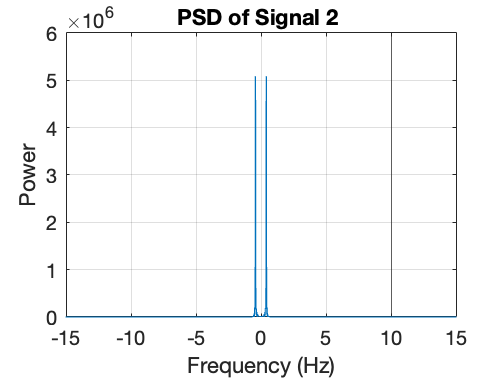


%DFT of signal s_t  

y2_T=y2(:)';      %y2 ORIGINALLY A ROW VECTOR, MAKING IT A COLUMN VECTOR 

%fs_sin=200;
%auto_corr_y2_T = xcorr(y2_T);
%Sin_rec = fft(y2_T); %does the DFT of signal
%N_0 = length(y2_T);    %Creates vector same size as voice_data 
%f_k = (0:N_0-1)/N_0*fs_sin;  %Creates frequency axis 
%figure;
%f_k_shift = f_k - fs_sin/2; % shift the axis so that it is centered at 0

%plot(f_k_shift,fftshift( abs(Sin_rec) )); %plots the new graph
%xlabel('Frequency (Hz)');
%ylabel('Magnitude');
%set(gca, 'YScale', 'log'); 
%yticks(10.^(-3:1:3));
%title("Freq of Sin ");
%grid on;
%xlim([-15 15]);
%xline(10);


%PSD of signal 2 
%autocorrelation 
auto_corr_y2_T = xcorr(y2_T);
%DFT of Zoom voice 
power_s2_rec = fft(auto_corr_y2_T); %does the DFT of signal
N_0 = length(auto_corr_y2_T);    %Creates vector same size as voice_data 
f_k = (0:length(auto_corr_y2_T)-1)/N_0*fs_sin;  %Creates frequency axis 
figure;
f_k_shift = f_k - fs_sin/2; % shift the axis so that it is centered at 0
plot(f_k_shift,fftshift(abs(power_s2_rec))); %plots the new graph
xlabel('Frequency (Hz)');
ylabel('Power');
%set(gca, 'YScale', 'log'); 
%yticks(10.^(-3:1:4));
title("PSD of Signal 2 ");
grid on;
xline(10);
xlim([-15 15])

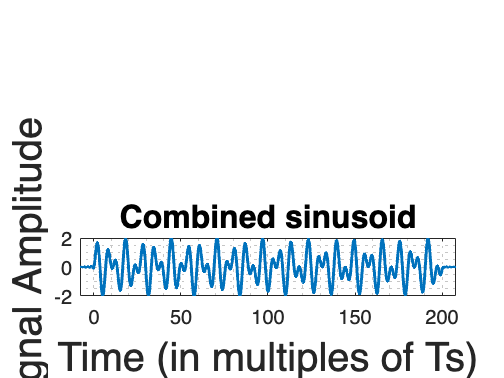

%Reconstruction of combines cosines 
%block 10


n_symb = length(c_t)-1; % To not resample the signal, This is to ge the whole og signal
t = 1:n_symb;               %Create t axis w step size of 1 
%x = 1;%randi(size(t))'

    %ATTEMPTS
    %t_sin = (0:n_symb-1)/fs_sin;
    %sin_freq =10;           %frequency of sin wave 
    %s_t= sin(2*pi*sin_freq*t_sin);

    d2 = c_t(1:n_symb)';   %This works as we just take points from the sin
    %d2 = interp1(t_sinusoid, s_t, t_l, 'linear')';
  
%t_sinusoid=0:0.005:1;
%d2 = interp1(t_sinusoid, s_t, t, 'linear')';

%d2 = (2*randi([0 1],1,n_symb))'-1; % Polar RZ signaling
span = 8 ; %Span of the output signal in symbols
ts = linspace(-span,n_symb+span,(n_symb+span)*25); % each symbol will have 25 time samples for convenience
[Ts,T] = ndgrid(ts,t);
y = sinc(Ts - T); % unit sinc pulse
%y1 = sinc(Ts - T)*d1; % this is sinc interpolation, used for recontruction
y2 = sum(d2'.*sinc(Ts - T),2); % Mutiply with data and add sinc pulse for each time


ax2=subplot(212);
plot(ts,y2,'Linewidth',1.5); hold on; % received RC pulses
%stem(t,d2,'o','filled');  % Sample points
xlabel ('Time (in multiples of Ts)','FontSize',20), ylabel('Signal Amplitude','FontSize',20)
title('Combined sinusoid','FontSize',16)
grid minor;

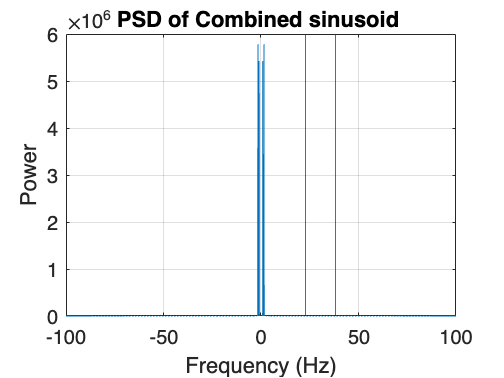


y2_T=y2(:)';      %y2 ORIGINALLY A ROW VECTOR, MAKING IT A COLUMN VECTOR 


auto_corr_y2_T = xcorr(y2_T);
%DFT of Zoom voice 
power_s2_rec = fft(auto_corr_y2_T); %does the DFT of signal
N_0 = length(auto_corr_y2_T);    %Creates vector same size as voice_data 
f_k = (0:length(auto_corr_y2_T)-1)/N_0*fs_sin;  %Creates frequency axis 
figure;
f_k_shift = f_k - fs_sin/2; % shift the axis so that it is centered at 0
plot(f_k_shift,fftshift(abs(power_s2_rec))); %plots the new graph
xlabel('Frequency (Hz)');
ylabel('Power');
%set(gca, 'YScale', 'log'); 
%yticks(10.^(-3:1:4));
title("PSD of Combined sinusoid ");
grid on;
xline(38);
xline(23);

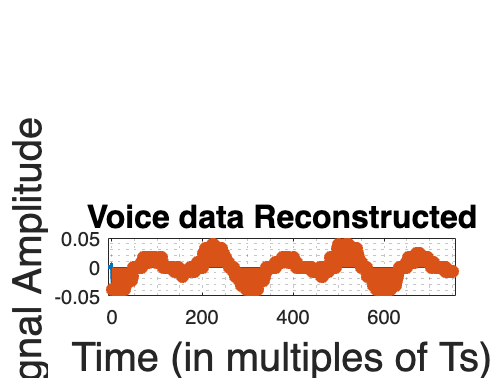

%Reconstruction of voice 
%block 11

n_symb = length(voice_data_zoom)-1; % To not resample the signal, This is to ge the whole og signal
n_symb = 750;
t = 1:(n_symb);               %Create t axis w step size of 1 
%x = 1;%randi(size(t))'

    %ATTEMPTS
    %t_sin = (0:n_symb-1)/fs_sin;
    %sin_freq =10;           %frequency of sin wave 
    %s_t= sin(2*pi*sin_freq*t_sin);

    d2 = voice_data_zoom(1:(n_symb))';   %This works as we just take points from the sin
    %d2 = interp1(t_sinusoid, s_t, t_l, 'linear')';
  
%t_sinusoid=0:0.005:1;
%d2 = interp1(t_sinusoid, s_t, t, 'linear')';

%d2 = (2*randi([0 1],1,n_symb))'-1; % Polar RZ signaling
span = 8 ; %Span of the output signal in symbols
ts = linspace(-span,n_symb+span,(n_symb+span)*25); % each symbol will have 25 time samples for convenience
[Ts,T] = ndgrid(ts,t);
y = sinc(Ts - T); % unit sinc pulse
%y1 = sinc(Ts - T)*d1; % this is sinc interpolation, used for recontruction
y2 = sum(d2'.*sinc(Ts - T),2); % Mutiply with data and add sinc pulse for each time


ax2=subplot(212);
plot(ts,y2,'Linewidth',1.5); hold on; % received RC pulses
stem(t,d2,'o','filled');  % Sample points
xlabel ('Time (in multiples of Ts)','FontSize',20), ylabel('Signal Amplitude','FontSize',20)
title('Voice data Reconstructed','FontSize',16)
grid minor;

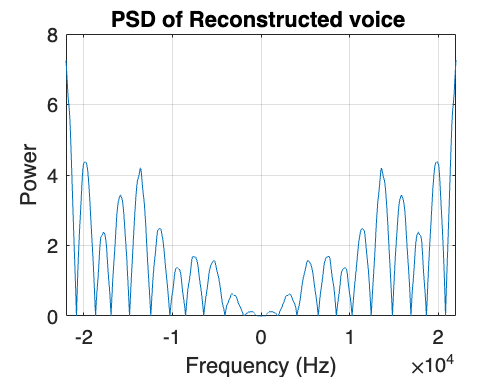


y_voice_T=y2(:)';      %y2 ORIGINALLY A ROW VECTOR, MAKING IT A COLUMN VECTOR 


auto_corr_y_voice_T = xcorr(y_voice_T);
%DFT of Zoom voice 
power_s2_rec = fft(auto_corr_y_voice_T); %does the DFT of signal
N_0 = length(auto_corr_y_voice_T);    %Creates vector same size as voice_data 
f_k = (0:length(auto_corr_y_voice_T)-1)/N_0*f_s;  %Creates frequency axis 
figure;
f_k_shift = f_k - f_s/2; % shift the axis so that it is centered at 0
plot(f_k_shift,fftshift(abs(auto_corr_y_voice_T))); %plots the new graph
xlabel('Frequency (Hz)');
ylabel('Power');
%set(gca, 'YScale', 'log'); 
%yticks(10.^(-3:1:4));
title("PSD of Reconstructed voice ");
grid on;

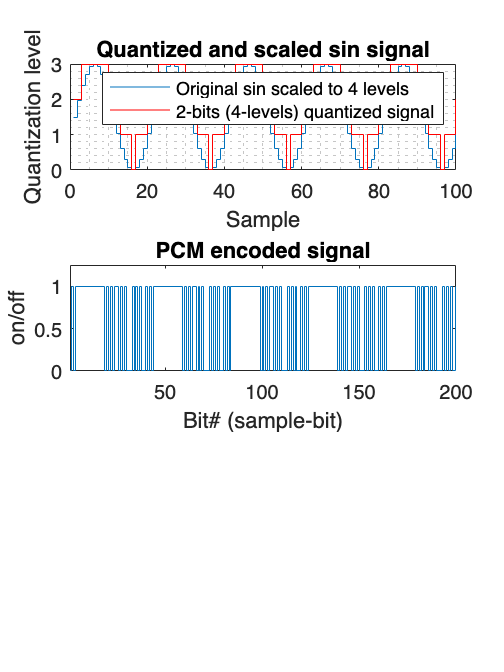

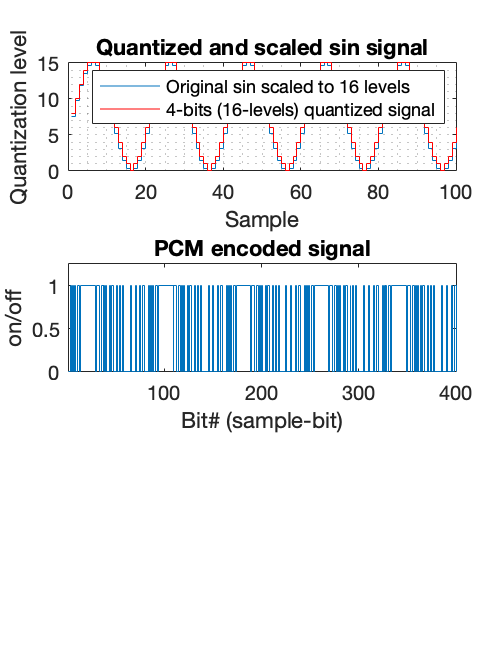

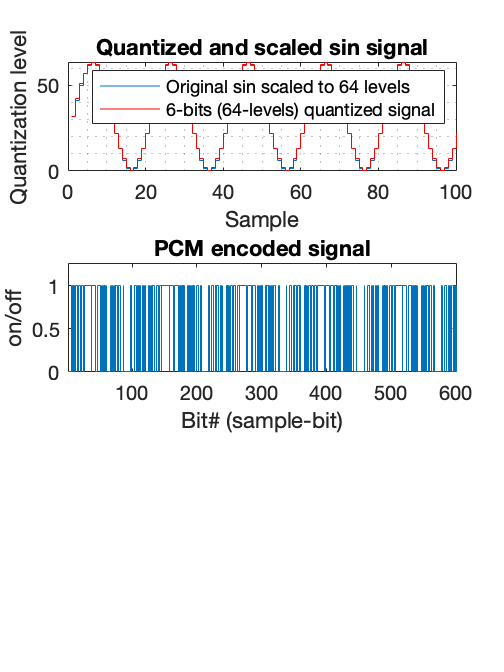

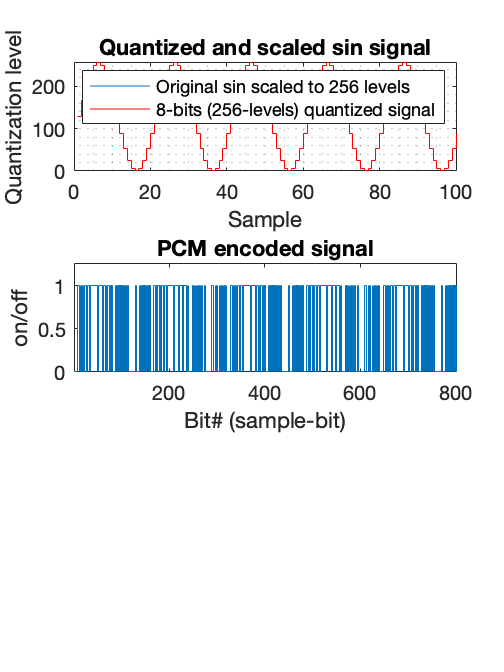

%PCM FOR Signal S_t 
%% Load data from file
%block 12

%addpath('/Volumes/GoogleDrive/My Drive/Websites/Spring22_ECE471_CommSys/MLX_Notes/chapter-3'); % add the location of your mlx files and the sound files here
%[X, Fs]=audioread('ringin.wav'); % sample values (X) and sampling frequency (Fs); ('ringin.wav' is mono channel audio)

%Re-defining S_t
        t= 0:0.005:1;
        sin_freq =10;           %frequency of sin wave 
        s_t= sin(2*pi*sin_freq*t);
        fs_sin = 1 / (t(2) - t(1)); % Compute sampling frequency from time st

X = s_t;
N = 1e2; % # of samples to be used for PCM encoding. You can change any range and see how the plot changes. 
X=X(1:N); % Using first N samples for demonstration

%% Normalizing in the range of [0 1];
X=X-min(X);     % to adjust in the range of 0 to max(X) - min(X)
X=X./max(X);    % Normalize the sample values in the range of [0~1]
X=(2*X-1);      % 2*X will change the range to [0~2] and (-1) will make the range [-1~1]
Vpp=max(X)-min(X);       % peak to peak voltage will be 2 because of the normalizatin above

%% PCM Algorithm demonstration on different bit levels
SQNR = zeros(1,1);
for i=2:2:8 % PCM modulation bits / sample
    q=2^i;  % # Quantizer Levels
    r=i*fs_sin; % signaling rate 'number of bits to be transmitted per second'
    delta=Vpp/q; % step size (delta)
    
    % if (delta) is very small then we can assume that the quantization error is uniformaly distributed.
    Pn=(delta^2)/12;       % Quantization noise power (based on uniform noise distribution assumption)
    Ps=sum(X.^2);          % Normalized signal power
    SQNR(i/2)=10*log10(Ps/Pn);  % Signal to quantization noise ratio in PCM in dB
    
    Xs=(q-1)*(X+1)/2;           % 'Xs' is scaled 'X' to quantization levels
    Xs_quant=quantiz(Xs,0:q-2); % Scaled quantized signal
    
    %% Plotting scaled and quantized signals 
    
    %subplot(8,1,i-1)
    figure()
    subplot(3,1,1)
    stairs(Xs);                   % Scaled signal
    hold on
    stairs(Xs_quant,'r');         % Scaled signal
    hold off
    legend(sprintf('Original sin scaled to %d levels',q),sprintf('%d-bits (%d-levels) quantized signal',i,q));
    title('Quantized and scaled sin signal');
    xlabel('Sample');
    ylabel('Quantization level');
    grid minor
    
    %% PCM encoded signal (pulse train)
    Xs_encod=[];
    for j=1:length(Xs_quant)
         Xs_encod=[Xs_encod dec2binvec(Xs_quant(j),i)];
    end
    %subplot(8,1,i)
    subplot(3,1,2)
    stairs(Xs_encod);       % PCM encoded signal (pulse-train)
    axis([1 length(Xs_encod) 0 1.25]);
    title('PCM encoded signal');
    xlabel('Bit# (sample-bit)')
    ylabel('on/off')
    
    %% Plot the spectrum of the PCM signal
    % Find the bit-width
    
    %subplot(3,1,3)
    %stem(fftshift(abs(fft((xcorr(Xs_encod(1:100),Xs_encod(1:100)))))))
    
    k = gcf;
    k.Position = [10 10 600 800];
end

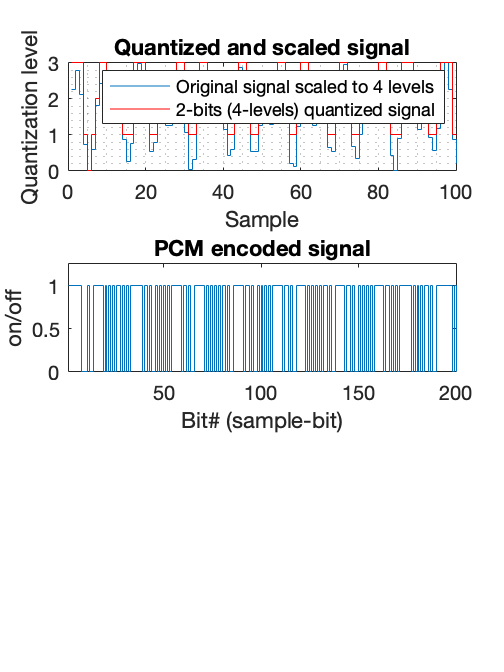

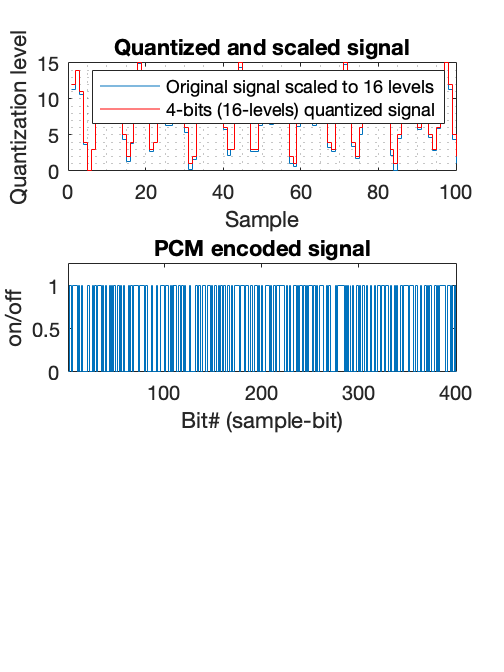

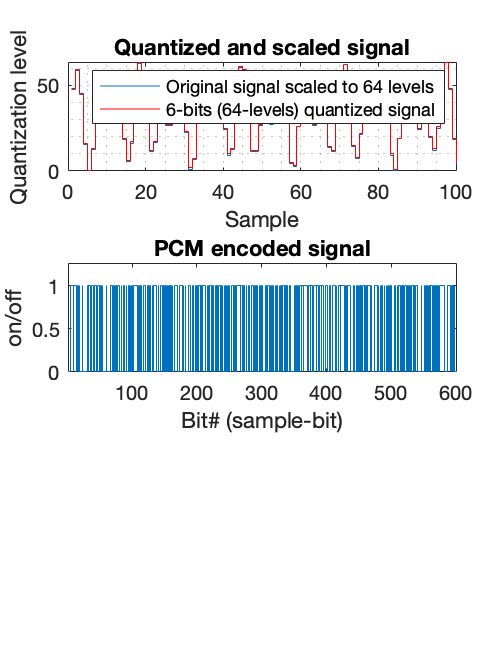

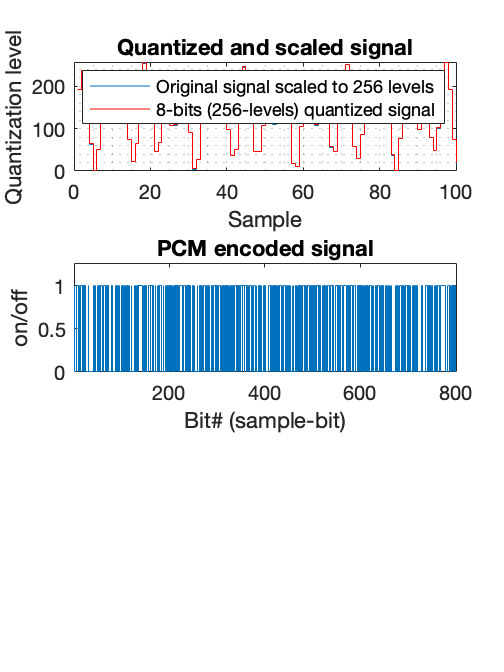




% PCM for Signal 2 or combined sinusoid c_t 

        %COMBINED SINUSOID 
        t= 0:0.005:1;
        fs_sin = 1 / (t(2) - t(1)); % Compute sampling frequency from time st


        cos_freq =23;
        c_t= cos(2*pi*cos_freq*t)+sin(2*pi*(cos_freq+15)*t);    %Linear Comb 


%[X, Fs]=audioread('ringin.wav'); % sample values (X) and sampling frequency (Fs); ('ringin.wav' is mono channel audio)

X=c_t;
N = 1e2; % # of samples to be used for PCM encoding. You can change any range and see how the plot changes. 
X=X(1:N); % Using first N samples for demonstration

%% Normalizing in the range of [0 1];
X=X-min(X);     % to adjust in the range of 0 to max(X) - min(X)
X=X./max(X);    % Normalize the sample values in the range of [0~1]
X=(2*X-1);      % 2*X will change the range to [0~2] and (-1) will make the range [-1~1]
Vpp=max(X)-min(X);       % peak to peak voltage will be 2 because of the normalizatin above

%% PCM Algorithm demonstration on different bit levels
SQNR = zeros(1,1);
for i=2:2:8 % PCM modulation bits / sample
    q=2^i;  % # Quantizer Levels
    r=i*fs_sin; % signaling rate 'number of bits to be transmitted per second'
    delta=Vpp/q; % step size (delta)
    
    % if (delta) is very small then we can assume that the quantization error is uniformaly distributed.
    Pn=(delta^2)/12;       % Quantization noise power (based on uniform noise distribution assumption)
    Ps=sum(X.^2);          % Normalized signal power
    SQNR(i/2)=10*log10(Ps/Pn);  % Signal to quantization noise ratio in PCM in dB
   
    Xs=(q-1)*(X+1)/2;           % 'Xs' is scaled 'X' to quantization levels
    Xs_quant=quantiz(Xs,0:q-2); % Scaled quantized signal
    
    %% Plotting scaled and quantized signals 
    
    %subplot(8,1,i-1)
    figure()
    subplot(3,1,1)
    stairs(Xs);                   % Scaled signal
    hold on
    stairs(Xs_quant,'r');         % Scaled signal
    hold off
    legend(sprintf('Original signal scaled to %d levels',q),sprintf('%d-bits (%d-levels) quantized signal',i,q));
    title('Quantized and scaled signal');
    xlabel('Sample');
    ylabel('Quantization level');
    grid minor
    
    %% PCM encoded signal (pulse train)
    Xs_encod=[];
    for j=1:length(Xs_quant)
         Xs_encod=[Xs_encod dec2binvec(Xs_quant(j),i)];
    end
    %subplot(8,1,i)
    subplot(3,1,2)
    stairs(Xs_encod);       % PCM encoded signal (pulse-train)
    axis([1 length(Xs_encod) 0 1.25]);
    title('PCM encoded signal');
    xlabel('Bit# (sample-bit)')
    ylabel('on/off')
    
    %% Plot the spectrum of the PCM signal
    % Find the bit-width
    
    %subplot(3,1,3)
    %stem(fftshift(abs(fft((xcorr(Xs_encod(1:100),Xs_encod(1:100)))))))
    
    k = gcf;
    k.Position = [10 10 600 800];
end

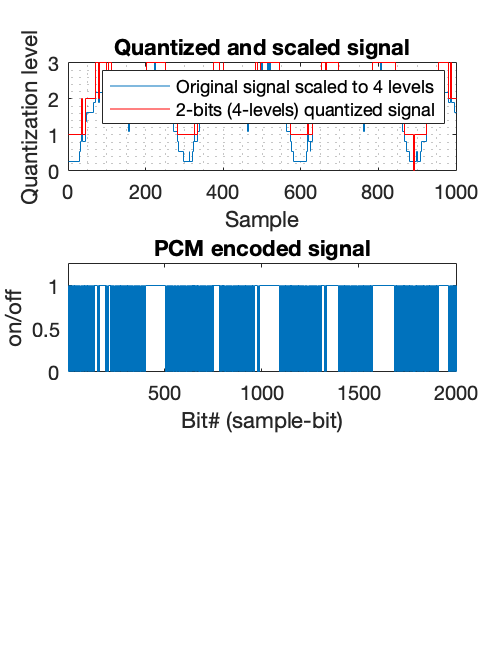

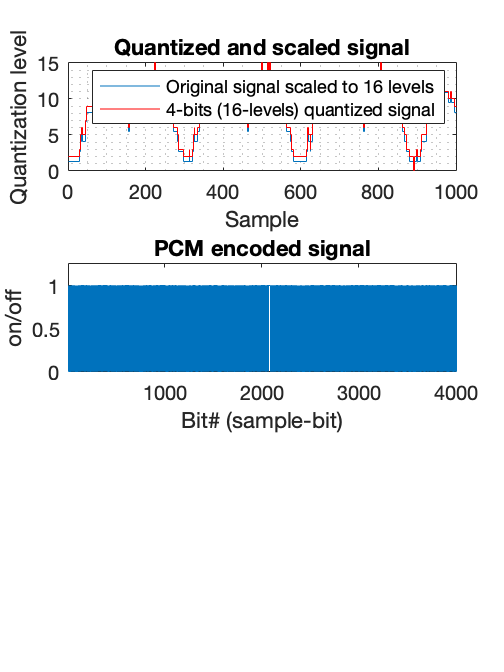

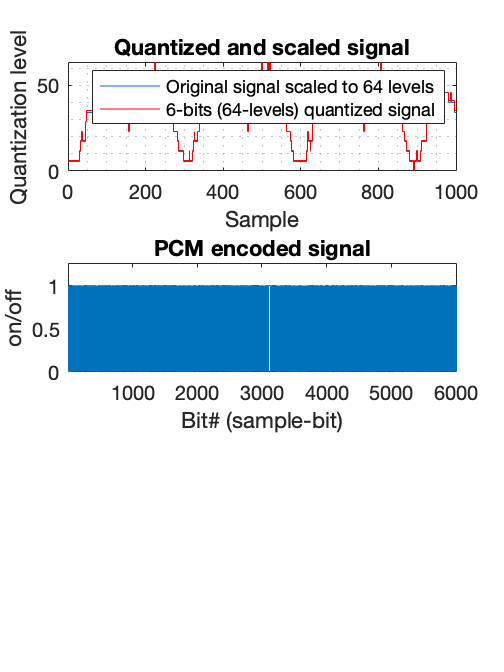

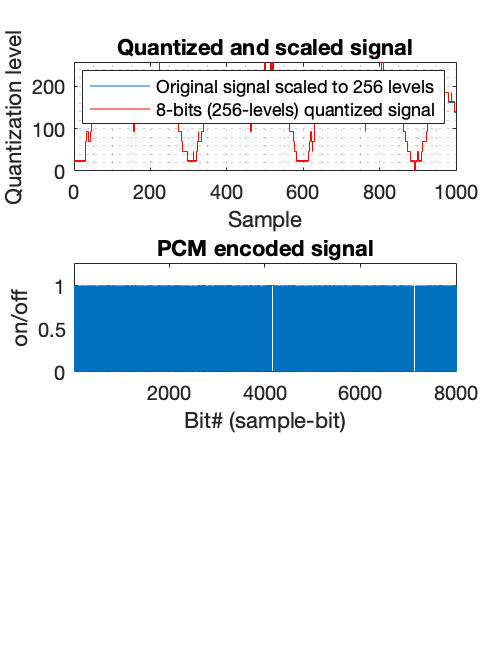




%Voice signal (Zoomed in version -> less data) 

%Signal 
X=voice_data_zoom;

%[X, Fs]=audioread('ringin.wav'); % sample values (X) and sampling frequency (Fs); ('ringin.wav' is mono channel audio)
N = 1e3; % # of samples to be used for PCM encoding. You can change any range and see how the plot changes. 
X=X(1:N); % Using first N samples for demonstration

%% Normalizing in the range of [0 1];
X=X-min(X);     % to adjust in the range of 0 to max(X) - min(X)
X=X./max(X);    % Normalize the sample values in the range of [0~1]
X=(2*X-1);      % 2*X will change the range to [0~2] and (-1) will make the range [-1~1]
Vpp=max(X)-min(X);       % peak to peak voltage will be 2 because of the normalizatin above

%% PCM Algorithm demonstration on different bit levels
SQNR = zeros(1,1);
for i=2:2:8 % PCM modulation bits / sample
    q=2^i;  % # Quantizer Levels
    r=i*f_s; % signaling rate 'number of bits to be transmitted per second'
    delta=Vpp/q; % step size (delta)
    
    % if (delta) is very small then we can assume that the quantization error is uniformaly distributed.
    Pn=(delta^2)/12;       % Quantization noise power (based on uniform noise distribution assumption)
    Ps=sum(X.^2);          % Normalized signal power
    SQNR(i/2)=10*log10(Ps/Pn);  % Signal to quantization noise ratio in PCM in dB
    
    Xs=(q-1)*(X+1)/2;           % 'Xs' is scaled 'X' to quantization levels
    Xs_quant=quantiz(Xs,0:q-2); % Scaled quantized signal
    
    %% Plotting scaled and quantized signals 
    
    %subplot(8,1,i-1)
    figure()
    subplot(3,1,1)
    stairs(Xs);                   % Scaled signal
    hold on
    stairs(Xs_quant,'r');         % Scaled signal
    hold off
    legend(sprintf('Original signal scaled to %d levels',q),sprintf('%d-bits (%d-levels) quantized signal',i,q));
    title('Quantized and scaled signal');
    xlabel('Sample');
    ylabel('Quantization level');
    grid minor
    
    %% PCM encoded signal (pulse train)
    Xs_encod=[];
    for j=1:length(Xs_quant)
         Xs_encod=[Xs_encod dec2binvec(Xs_quant(j),i)];
    end
    %subplot(8,1,i)
    subplot(3,1,2)
    stairs(Xs_encod);       % PCM encoded signal (pulse-train)
    axis([1 length(Xs_encod) 0 1.25]);
    title('PCM encoded signal');
    xlabel('Bit# (sample-bit)')
    ylabel('on/off')
    
    %% Plot the spectrum of the PCM signal
    % Find the bit-width
    
    %subplot(3,1,3)
    %stem(fftshift(abs(fft((xcorr(Xs_encod(1:100),Xs_encod(1:100)))))))
    
    k = gcf;
    k.Position = [10 10 600 800];
end

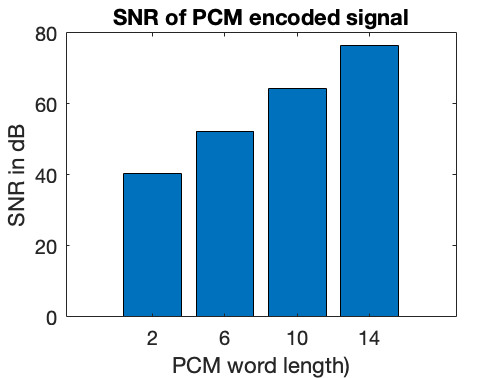


figure()
bar(2:4:16,SQNR)
title('SNR of PCM encoded signal');
xlabel('PCM word length)')
ylabel('SNR in dB')




%For the 3 portions of code above, the objective is to 

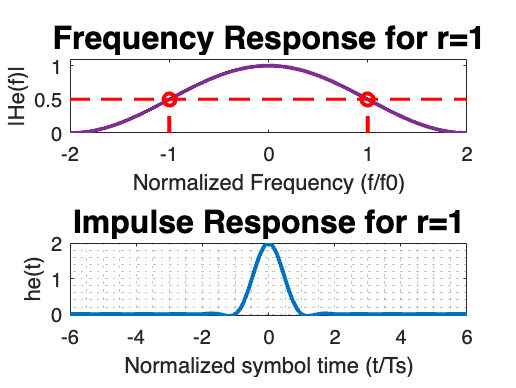


%PULSE SHAPING
%block 13
                                       %STATUS: IN PROGRESS 

%Raised Cosine pulse

%addpath('/Users/ericdutan/Desktop/Spring 2025/Communications/MLX_Support_Files'); % add the location of your mlx files

r = 1; %roll-off factor of the RC pulse %input('Enter value of r between 0.01 and 1:');
fo = 1; % f0 = fs/2
B = fo.*(1+r);
fl = B.*(1-r)/(1+r);
fd = (B-fl)/2;

% Evaluate and Plot the Frequency Response using Eq (3-69)
f = 0:B/500:B;
a = zeros(length(f),1);
window = a;
b = a;

window = PULSE(window,f,fl,B);
for i = 1:1:length(f)
  if (f(i) < fl)
    a(i) = 1;
  end
  b(i) = 0.5*(1+cos(pi*(f(i)-fl)/(2*fd)));
end
He = a + b.*window;

subplot(211)
plot([-fliplr(f) f],[fliplr(He') He'],'LineWidth',2); hold on;
plot(-2:0.5:2, 0.5*ones(1,length(-2:0.5:2)),'r--','LineWidth',1.5);
stem([-1 1],[0.5 0.5],'r--','LineWidth',2);
xlabel('Normalized Frequency (f/f0)');
ylabel('|He(f)|');
axis([-2 2 0 1.1])
title(['Frequency Response for r=',num2str(r)], FontSize=16); grid minor

% Evaluate and Plot the Impulse Response using Eq (3-73)
fd = B*r/(1+r);
td = 3/(50*fo);
t = 0:td:50*td;

xo = 2*pi*fo*t;
xd = 2*pi*fd*t;

temp1 = SA(xo);
he = zeros(length(t),1);

for i = 1:1:length(t)
  he(i) = 2*fo*temp1(i)*cos(xd(i))/(1-(4*fd*t(i))^2);
end

subplot(212)
plot([-fliplr(t*2) t*2],[fliplr(he') he'],'LineWidth',2);
xlabel('Normalized symbol time (t/Ts)');
ylabel('he(t)');
title(['Impulse Response for r=',num2str(r)],FontSize=16);
grid minor;
for i = 1:1:length(f)
  if (f(i) < fl)
    a(i) = 1;
  end
  b(i) = 0.5*(1+cos(pi*(f(i)-fl)/(2*fd)));
end
He = a + b.*window;

subplot(211)
plot([-fliplr(f) f],[fliplr(He') He'],'LineWidth',2); hold on;
plot(-2:0.5:2, 0.5*ones(1,length(-2:0.5:2)),'r--','LineWidth',1.5);
stem([-1 1],[0.5 0.5],'r--','LineWidth',2);
xlabel('Normalized Frequency (f/f0)');
ylabel('|He(f)|');
axis([-2 2 0 1.1])
title(['Frequency Response for r=',num2str(r)], FontSize=16); grid minor

% Evaluate and Plot the Impulse Response using Eq (3-73)
fd = B*r/(1+r);
td = 3/(50*fo);
t = 0:td:50*td;

xo = 2*pi*fo*t;
xd = 2*pi*fd*t;

temp1 = SA(xo);
he = zeros(length(t),1);

for i = 1:1:length(t)
  he(i) = 2*fo*temp1(i)*cos(xd(i))/(1-(4*fd*t(i))^2);
end

imp_rc = [fliplr(he') he'];

subplot(212)
plot([-fliplr(t*2) t*2],imp_rc,'LineWidth',2);
xlabel('Normalized symbol time (t/Ts)');
ylabel('he(t)');
title(['Impulse Response for r=',num2str(r)],FontSize=16);
grid minor;

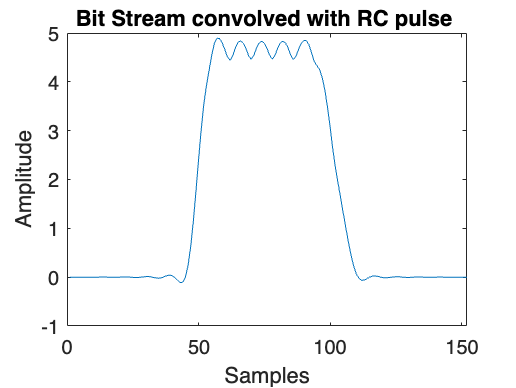

%Convolution with Impulse respone of RC and PCM signal 
%block 14
PCM_voice_samp = Xs_encod(50:100);


conv_pcm_voice = conv(PCM_voice_samp,imp_rc );
figure ();
plot( conv_pcm_voice);
xlabel("Samples");
ylabel("Amplitude");
title("Bit Stream convolved with RC pulse ");

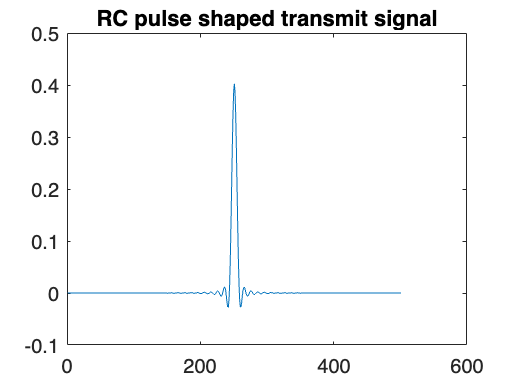

% Convolution with rcosdesign();
%block 15
Trans_sig  = rcosdesign(r,50,10);%r = roll-off, 50-> symbol duration, 10-> smaples per symbol
figure();
plot(Trans_sig);
title('RC pulse shaped transmit signal');

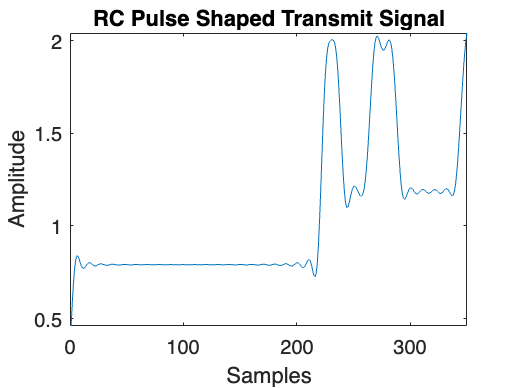


tx_sign=conv(Xs_encod,Trans_sig,'same');
plot(tx_sign);
xlabel('Samples');
ylabel("Amplitude");
title("RC Pulse Shaped Transmit Signal");
xlim([0 350]);

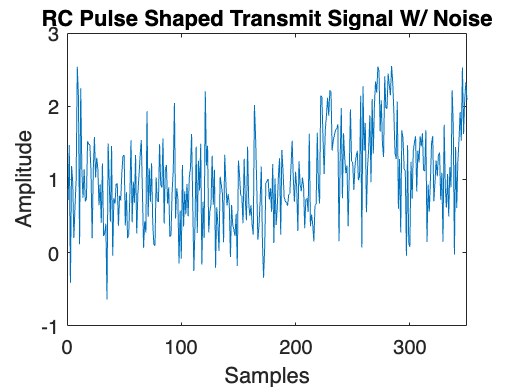

%Adding noise
%block 16
noisy_signal = awgn(tx_sign, 10, 'measured');
plot(noisy_signal);
xlabel('Samples');
ylabel("Amplitude");
title("RC Pulse Shaped Transmit Signal W/ Noise");
xlim([0 350]);

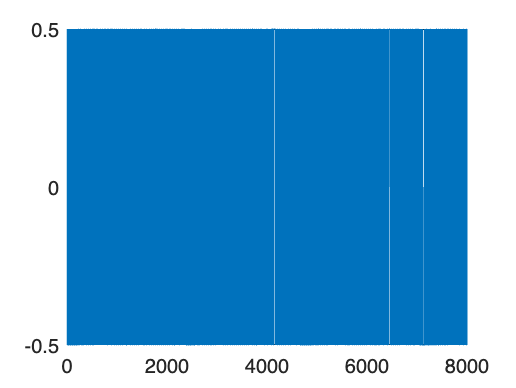

                            %Part B
%Block 17
voice_bit=(Xs_encod-.5);         %shifting down to make polar
r=0.5;
Trans_sig  = rcosdesign(r,50,10);%r = roll-off, 50-> symbol duration, 10-> smaples per symbol
plot(voice_bit);

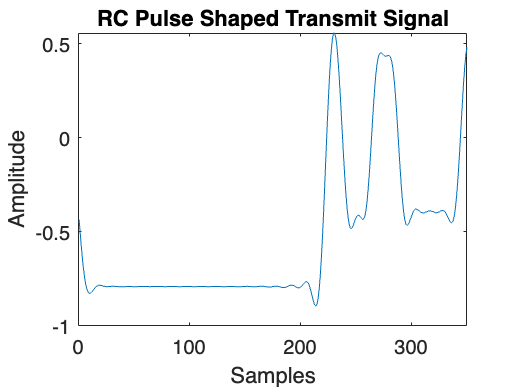

                        %Part B.b
%Block 18
tx_sign=conv(voice_bit,Trans_sig,'same');
plot(tx_sign);
xlabel('Samples');
ylabel("Amplitude");
title("RC Pulse Shaped Transmit Signal");
xlim([0 350]);

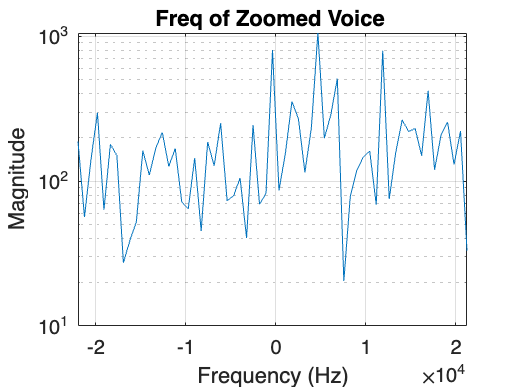


X_K_tx_sig = fft(tx_sign); %does the DFT of signal
X_K_tx_sig=X_K_tx_sig(1:61);
N_0 = length(X_K_tx_sig);    %Creates vector same size as voice_data 
f_k = (0:length(X_K_tx_sig)-1)/N_0*f_s;  %Creates frequency axis 
figure;
f_k_shift = f_k - f_s/2; % shift the axis so that it is centered at 0
plot(f_k_shift,fftshift(abs(X_K_tx_sig))); %plots the new graph
xlabel('Frequency (Hz)');
ylabel('Magnitude');
set(gca, 'YScale', 'log'); 

title("Freq of Zoomed Voice ");
grid on;

                        %Part B.c


function out = dec2binvec(dec,n)
%DEC2BINVEC Convert decimal number to a binary vector.
%
%    DEC2BINVEC(D) returns the binary representation of D as a binary
%    vector.  The least significant bit is represented by the first 
%    column.  D must be a -negative integer. 
% 
%    DEC2BINVEC(D,N) produces a binary representation with at least
%    N bits.
% 
%    Example:
%       dec2binvec(23) returns [1 1 1 0 1]
%
%    See also BINVEC2DEC, DEC2BIN.
%

%    MP 11-11-98
%    Copyright 1998-2003 The MathWorks, Inc.
%    $Revision: 1.5.2.4 $  $Date: 2003/08/29 04:40:56 $

% Error if dec is not defined.
if nargin < 1
   error('daq:dec2binvec:argcheck', 'D must be defined.  Type ''daqhelp dec2binvec'' for more information.');
end

% Error if D is not a double.
if ~isa(dec, 'double')
   error('daq:dec2binvec:argcheck', 'D must be a double.');
end

% Error if a negative number is passed in.
if (dec < 0)
   error('daq:dec2binvec:argcheck', 'D must be a positive integer.');
end

% Convert the decimal number to a binary string.
switch nargin
case 1
   out = dec2bin(dec);
case 2
   out = dec2bin(dec,n);
end

% Convert the binary string, '1011', to a binvec, [1 1 0 1].
out = str2num([fliplr(out);blanks(length(out))]')';
end



function w = PULSE(w,t,tbegin,tend)
% FILE: PULSE.m
% CALL: w = PULSE(w,t,tbegin,tend)
% This function creates a square pulse.

% t = Input vector that corresponds to the discrete time values.
% w = Input vector that corresponds to the waveform.
% tbegin = defines the left edge of the pulse.
% tend = defines the right edge of the pulse.
    i = length(t);
    for (i = 1:length(t))
      if (t(i) >= tbegin & t(i) <= tend)
        w(i) = 1;
      end
    end
end


function y = SA(x)
    % File: SA.M
    % CALL: y = SA(x)
    % This function computes sin(x)/x.
    % x is assumed to be a "scalar" or a vector;
    
    x = x(:);
    y = zeros(length(x),1);
    
    for (i = 1:length(x))
      if (x(i) == 0)
        y(i) = 1;
      else
        y(i) = sin(x(i))/x(i);
      end
    end
end